# Sampling and Aliasing

## Sampling and Reconstruction at the Nyquist Frequency

Consider the analog signal $x_a(t) = \cos(20\,\pi\,t + \theta)$for $0 \le t \le 1$. It is sampled at $T_s = 0.05 $second intervals to obtain x[n]. Let $\theta = 0, \, \pi/6, \, \pi/4, \, \pi/2.$For each value of the $\theta$ values, perform the following.

- Plot $x_a(t)$ and superimpose x[n] on top of it using the plot(n,x,'o') function.

- Reconstruct the analog signal  from the samples x[n] using the sinc interpolation. Use $\Delta\,t = 0.001$, and superimpiose x[n] on it.

- You should observe that the resultant reconstruction in each case has the correct frequency but a different amplitude. Explain this observation. Comment on the role of the phase of $x_a(t)$on the sampling and reconstruction of signals.

Put your work here:

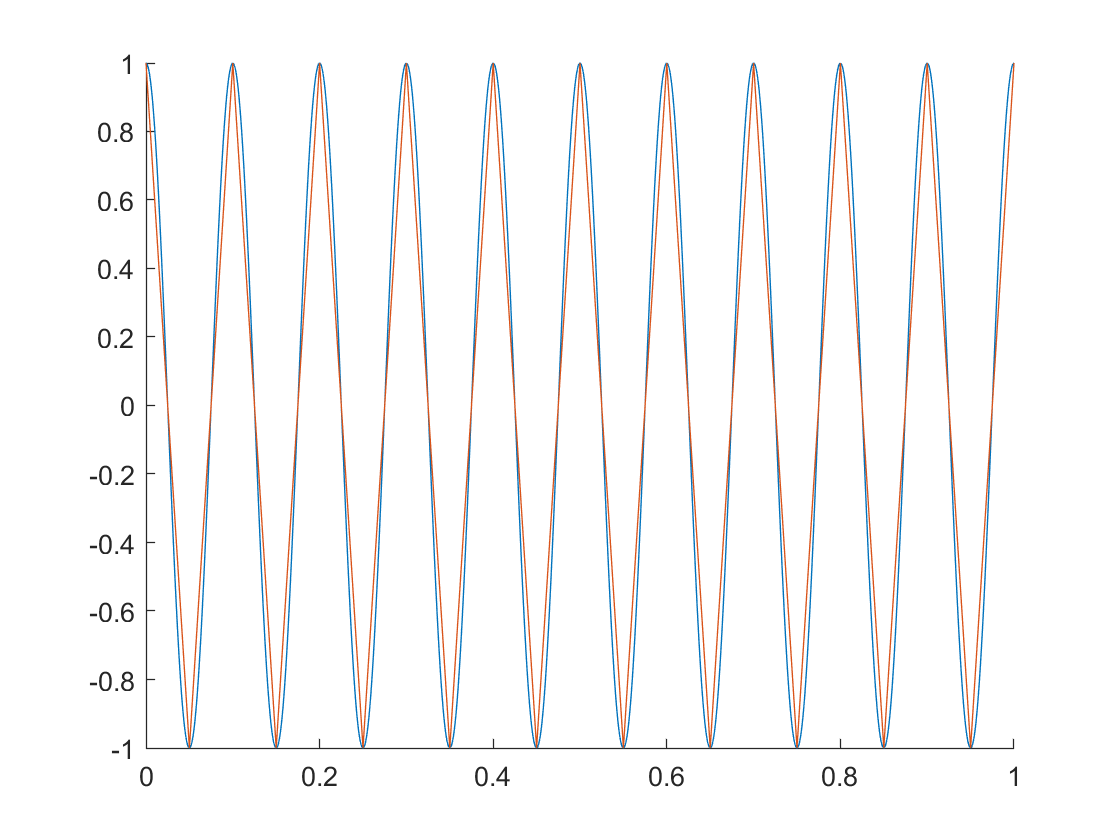

Error using stem (line 43)
X must be same length as Y.

%first set corresponds to xt, second xn
sampleDeltas = [0.001;0.05];
tvals = 0:sampleDeltas(1):1;
nvals = 0:sampleDeltas(2):1;


tOnesMat = ones([1,length(tvals)]);
nOnesMat = ones([1,length(nvals)]);

tFreqArgs = [1;1;1;1]*(20.*pi.*tvals);
nFreqArgs = [1;1;1;1]*(20.*pi.*nvals);

thetas = [0,pi/6,pi/4,pi/2];
strThetas = {'0','\pi/6','\pi/4','\pi/2'};
tPhaseArgs = thetas'*tOnesMat;
nPhaseArgs = thetas'*nOnesMat;

xt = cos(tFreqArgs+tPhaseArgs);
xn = cos(nFreqArgs+nPhaseArgs);

xRecon = zeros([4,size(tOnesMat,2)]);
xSinc = zeros([4,size(tOnesMat,2)]);
indexRatio = size(tvals,2)./size(nvals,2);
sincKernal = sinc([-0.5:0.001:0.5]);

for k = 1:size(xn,2)
    xRecon(:,round((k).*indexRatio)) = xn(:,k); 
    
end
for k = 1:size(thetas)    
    xSinc(k,:) = conv(sincKernal,xRecon(k,:),'same');
end



close all;
for k = 1:size(xt,1)
    hold on;
    plot(tvals,xt(k,:)');
    plot(nvals,xn(k,:)');
    plot(tvals,xRecon(k,:)');
    plot(tvals, xSinc(k,:)');
    title(strcat(strcat('x = cos(20\pit+',strThetas(k)),')'));
    legend('x(t)','x[n]','zero padded x[n]', 'x[n], sinc interpolated');
    figure;
end

ut your explanations here:

P

## Aliasing with Images

We explore aliasing with sounds in Python. Here we explore aliasing with images.

Show an excellent image for the study of aliasing.

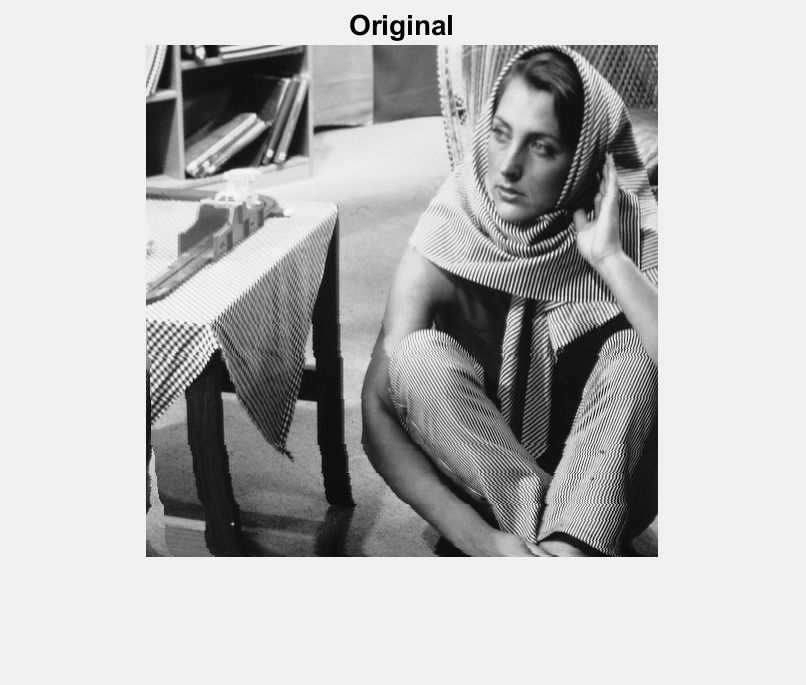

clc
clear all
close all

Im1 = imread('barbara_gray.bmp') ;
figure
set(gcf,'Visible','On')
imshow(Im1)
title('Original')

[height, width, depth] = size(Im1) 

height = 512

width = 512

depth = 1

Downsample the image with no prefiltering

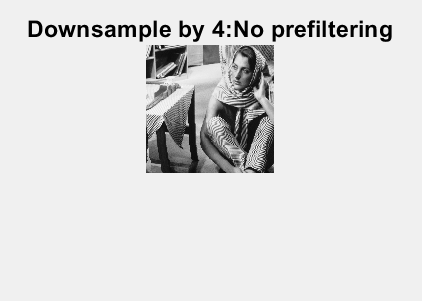

% in case bit depth is three (if trying other images)
Im2 = Im1(:,:,1) ;

% downsample no prefiltering
M = 4 ;
% write code to downsample the image by a factor of M
% put code here
%Im3 = imresize(Im2, [(1/M)*height, (1/M)*width]);
Im3 = Im2(1:M:height, 1:M:width);

% plot downsampled image
figure
set(gcf,'Visible','On')
imshow(Im3)
title(['Downsample by ' num2str(M) ':No prefiltering']) ;

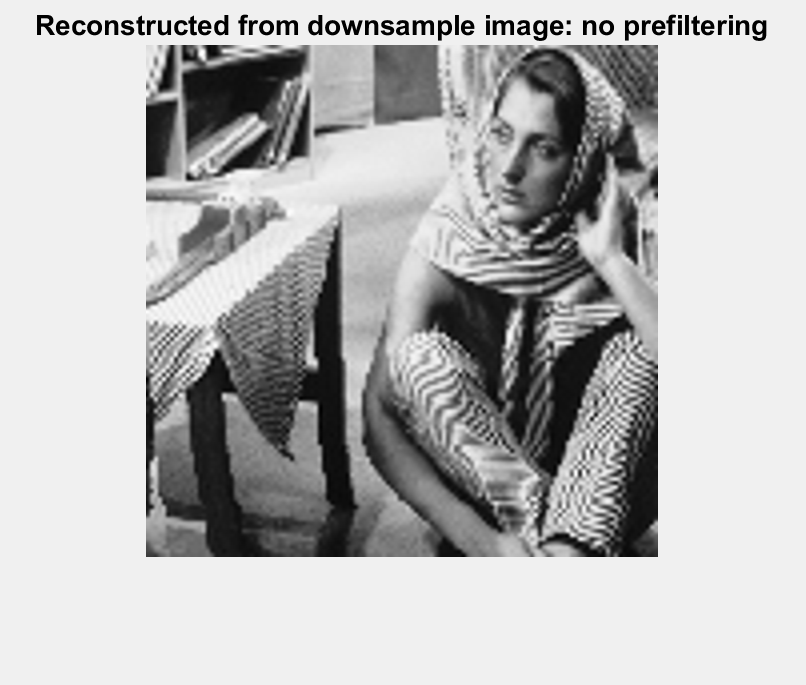


% reconstruct to original size
Im4 = imresize(Im3, [height,width],'bicubic');
figure
set(gcf,'Visible','On')
imshow(Im4)
title(['Reconstructed from downsample image: no prefiltering'])

Downsample with low-pass prefiltering

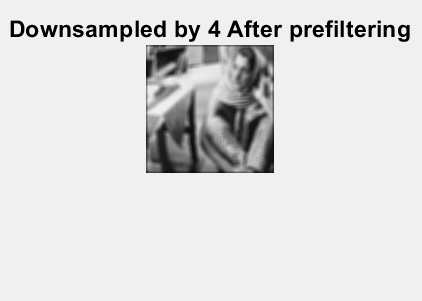

% downsample by a factor of M, after prefiltering
% apply a Gaussian filter to the image
% use the fspecial function to create a Gaussian filter
% explore reasonable values for the filter parameters
% use imfilter to apply the filter to the original image.
% put your code here

Im5 = Im2(1:M:height, 1:M:width);

filtSize = 5;
filtSigma = 5;
gaussFilter = fspecial('gaussian',filtSize,filtSigma);
Im6 = imfilter(Im5,gaussFilter);
% plot the downsampled image with prefiltering
figure
set(gcf,'Visible','On')
imshow(Im6)
title(['Downsampled by ' num2str(M) ' After prefiltering']) ;

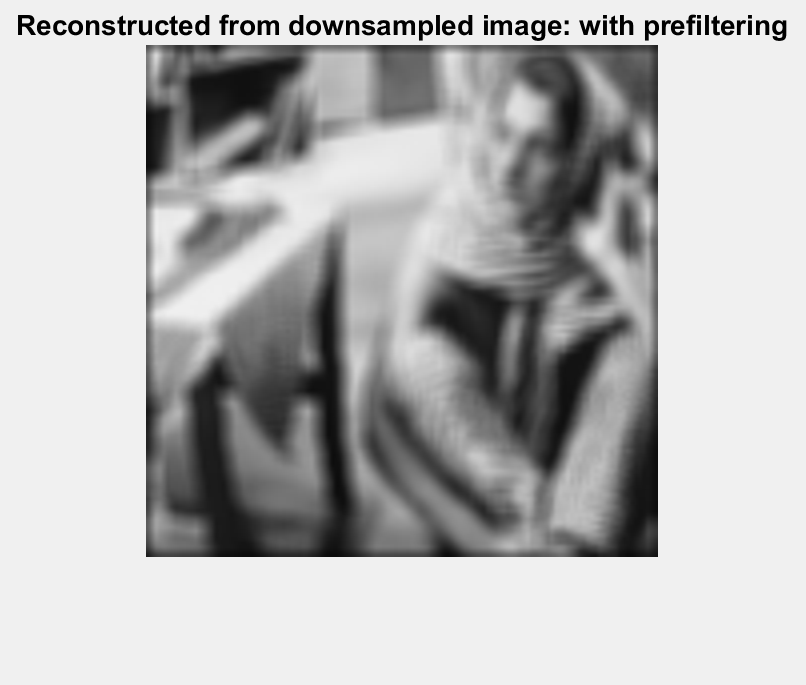


Im7 = imresize(Im6,[height,width],'bicubic') ;
figure
set(gcf,'Visible','On')
imshow(Im7)
title('Reconstructed from downsampled image: with prefiltering')

## Explain your Observations

Explain why aliasing should occur. Explain what you observe with aliasing. Explain why there is an improvement with the application of a prefilter.